%画出Ryy
ny = 7000;
Ryy_y3 = conv(y3, flipud(y3))

Ryy_y3 = 1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


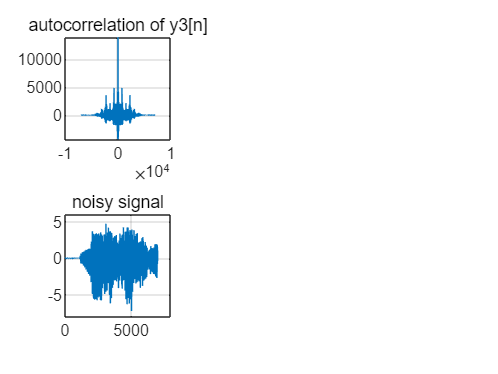


subplot(2, 3, 1);
plot(-ny+1 : ny - 1, Ryy_y3);
grid on;
title('autocorrelation of y3[n]');

subplot(2, 3, 4);
plot(0 : ny-1, y3);
grid on;
title('noisy signal');
axis([0, 8000, -8, 6]);
hold on;

%通过Ryy得到N1 = 750, N2 = 2250
N1 = 750;
N2 = 2250;
Rxx = conv(z, flipud(z)); %原声信号的Rxx

% Ryy3[n] = conv(y3[n] , y3[-n])

% → Ryy3[n] = (1 + a1^2 +a2^2) * Rxx[n] + a1 * Rxx[n-N1] + a1 * Rxx[n+N1] +
% a2 * % Rxx[n -N2] + a2 * Rxx[n+N2] + a1 * a2 * Rxx[n-N1+N2] + a1 * a2 * Rxx[n+N1-N2])

% → Ryy3[0] = (1 + a1^2 +a2^2) * Rxx[0] + a1 * Rxx[-N1] + a1 * Rxx[N1] +
% a2 * Rxx[-N2] + a2 * Rxx[N2] + a1 * a2 * Rxx[-N1+N2] + a1 * a2 * Rxx[N1-N2])

Ryy0 = Ryy_y3(ny);
Rxx0 = Rxx(ny);
Rxx_negN1 = Rxx(ny - N1);
Rxx_N1 = Rxx(ny + N1);
Rxx_negN2 = Rxx(ny - N2);
Rxx_N2 = Rxx(ny + N2);
Rxx_N2_N1 = Rxx(ny + N2 - N1);
Rxx_N1_N2 = Rxx(ny + N1 - N2);

% → Ryy3[1] = (1 + a1^2 +a2^2) * Rxx[1] + a1 * Rxx[1-N1] + a1 * Rxx[1+N1] +
% a2 * % Rxx[1-N2] + a2 * Rxx[1+N2] + a1 * a2 * Rxx[1-N1+N2] + a1 * a2 * Rxx[1+N1-N2])

Ryy1 = Ryy_y3(ny + 1);
Rxx1 = Rxx(ny + 1);
Rxx_negN1_1 = Rxx(ny + 1 - N1);
Rxx_N1_1 = Rxx(ny + 1 + N1);
Rxx_negN2_1 = Rxx(ny + 1 - N2);
Rxx_N2_1 = Rxx(ny + 1 + N2);
Rxx_N2_N1_1 = Rxx(ny + 1 + N2 - N1);
Rxx_N1_N2_1 = Rxx(ny + 1 + N1 - N2);

syms alpha1 alpha2;
S = solve([Ryy0 == (1 + alpha1^2 + alpha2^2)*Rxx0 + alpha1*(Rxx_negN1+Rxx_N1) + alpha2*(Rxx_negN2+Rxx_N2) + alpha1*alpha2*(Rxx_N1_N2+Rxx_N2_N1), ...
    Ryy1 == (1 + alpha1^2 + alpha2^2)*Rxx1 + alpha1*(Rxx_negN1_1+Rxx_N1_1) + alpha2*(Rxx_negN2_1+Rxx_N2_1) + alpha1*alpha2*(Rxx_N1_N2_1+Rxx_N2_N1_1)], [alpha1, alpha2]);
a1 = double(S.alpha1);
a2 = double(S.alpha2);

disp(a1);

   0.6769 + 0.0000i
   0.2696 + 0.0000i
  -0.2061 - 0.2130i
  -0.2061 + 0.2130i



disp(a2);

   0.6047 + 0.0000i
  -0.8030 + 0.0000i
   0.8791 - 0.0616i
   0.8791 + 0.0616i



%筛选其中的实数解
a1_real = [0.6769, 0.2696];
a2_real = [0.6047, -0.8030];
mini_norm = 100000;
best_alpha1 = 0;
best_alpha2 = 0;

for alpha1 = a1_real
    for alpha2 = a2_real
        x_temp = filter(1, [1, zeros(1, N1 - 1), alpha1, zeros(1, N2 - N1 - 1), alpha2], y3);
        Rxx_temp = conv(x_temp, flipud(x_temp)).';
        error = Rxx - Rxx_temp.';
        if norm(error, 2) < mini_norm
            mini_norm = norm(error, 2);
            disp(mini_norm);
            best_alpha1 = alpha1;
            best_alpha2 = alpha2;
        end
    end
end

   5.3701e+04

   2.8246e+04



a_y3 = [1, zeros(1, N1 - 1), best_alpha1, zeros(1, N2 - N1 - 1), best_alpha2];
x3 = filter(1, a_y3, y3); %还原y3为x3
sound(x3);
Rxx_x3 = conv(x3, flipud(x3));

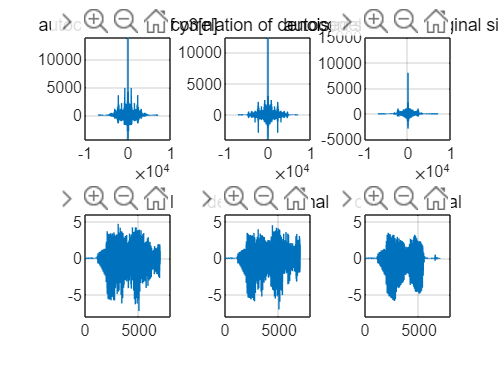

subplot(2, 3, 2);
plot(-ny+1 : ny-1, Rxx_x3);
grid on;
title('autocorrelation of denoised signal');

subplot(2, 3, 3);
plot(-ny+1 : ny-1, Rxx);
grid on;
title('autocorrelation of original signal');
axis([-10000, 10000, -5000, 15000]);
    

subplot(2, 3, 5);
plot(0 : ny-1, x3);
grid on;
title('denoised signal');
axis([0, 8000, -8, 6]);

subplot(2, 3, 6);
plot(0 : ny-1, z);
grid on;
title('original signal');
axis([0, 8000, -8, 6]);